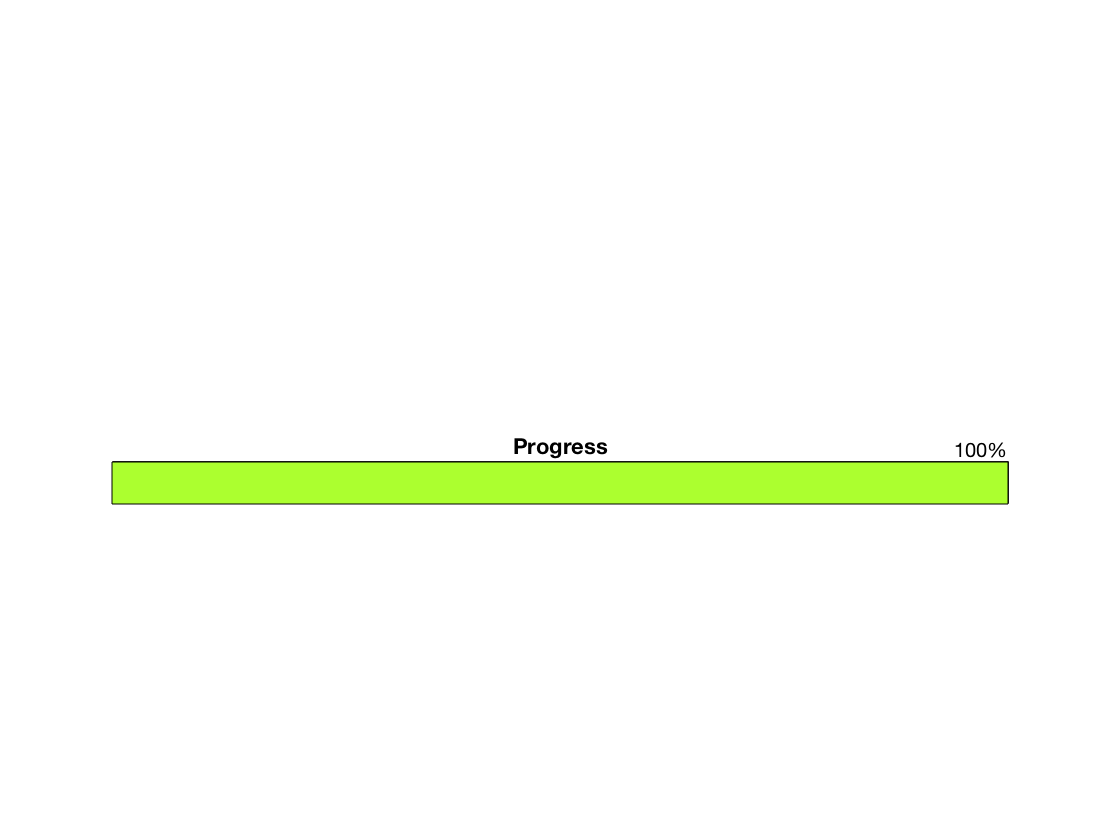


fh = clf();
ax = axes(fh,'Position',[.1 .4 .8 .05],'box','on','xtick',[],'ytick',[],...
    'color',[0.9375 0.9375 0.9375],'xlim',[0,1],'ylim',[0,1]); %gray94
title(ax,'Progress')
% Create empty patch that will be updated
ph = patch(ax,[0 0 0 0],[0 0 1 1],[0.67578 1 0.18359]); %greenyellow
% Create the percent-complete text that will be updated
th = text(ax,1,1,'0%','VerticalAlignment','bottom','HorizontalAlignment','right'); 


% Create processing loop that updates the progress bar
n = 100; 
for i = 1:n/2
    % update patch size and percentage text
    ph.XData = [0 i/n i/n 0]; 
    th.String = sprintf('%.0f%%',round(i/n*100)); 
    drawnow %update graphics
       
end

% ********Add the matching function at here ********** 


for i = n/2:n
    % update patch size and percentage text
    ph.XData = [0 i/n i/n 0]; 
    th.String = sprintf('%.0f%%',round(i/n*100)); 
    drawnow %update graphics
       
end